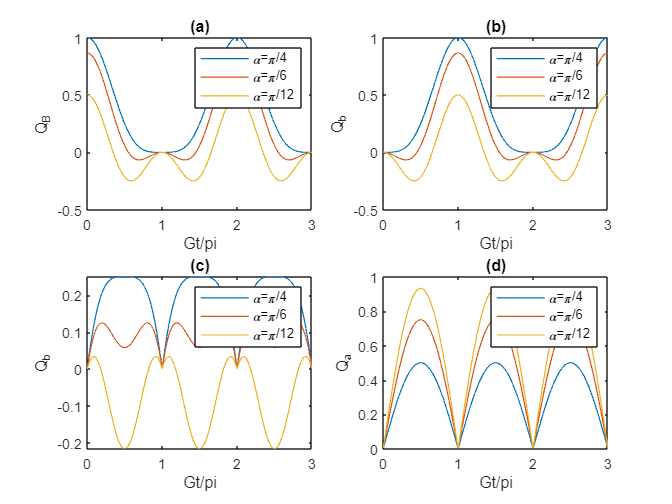

Gt=0:0.01*pi:3*pi;

alpha1=pi/4;
alpha2=pi/6;
alpha3=pi/12;

%C_AB(t)
Con_AB_1=(cos(Gt/2)).^2.*(abs(sin(2*alpha1))-2*((sin(Gt/2))).^2*cos(alpha1)^2);
Con_AB_2=(cos(Gt/2)).^2.*(abs(sin(2*alpha2))-2*((sin(Gt/2))).^2*cos(alpha2)^2);
Con_AB_3=(cos(Gt/2)).^2.*(abs(sin(2*alpha3))-2*((sin(Gt/2))).^2*cos(alpha3)^2);

figure;
subplot(2,2,1)
plot(Gt/pi, Con_AB_1,LineWidth=0.75);
hold on;
plot(Gt/pi, Con_AB_2,LineWidth=0.75);
plot(Gt/pi, Con_AB_3,LineWidth=0.75);
xlabel('Gt/pi');
ylabel('Q_A_B');
legend('\alpha=\pi/4','\alpha=\pi/6','\alpha=\pi/12');
title("(a)")

%C_ab(t)
Con_ab_1=(sin(Gt/2)).^2.*(abs(sin(2*alpha1))-2*((cos(Gt/2))).^2*cos(alpha1)^2); 
Con_ab_2=(sin(Gt/2)).^2.*(abs(sin(2*alpha2))-2*((cos(Gt/2))).^2*cos(alpha2)^2); 
Con_ab_3=(sin(Gt/2)).^2.*(abs(sin(2*alpha3))-2*((cos(Gt/2))).^2*cos(alpha3)^2);

subplot(2,2,2)
plot(Gt/pi, Con_ab_1,LineWidth=0.75);
hold on;
plot(Gt/pi, Con_ab_2,LineWidth=0.75);
plot(Gt/pi, Con_ab_3,LineWidth=0.75);
xlabel('Gt/pi');
ylabel('Q_a_b');
legend('\alpha=\pi/4','\alpha=\pi/6','\alpha=\pi/12');
title("(b)")

%C_Ab(t)
Con_Ab_1=1/2*(cos(alpha1))^2*abs(sin(Gt)).*(2*abs(tan(alpha1))-abs(sin(Gt)));
Con_Ab_2=1/2*(cos(alpha2))^2*abs(sin(Gt)).*(2*abs(tan(alpha2))-abs(sin(Gt)));
Con_Ab_3=1/2*(cos(alpha3))^2*abs(sin(Gt)).*(2*abs(tan(alpha3))-abs(sin(Gt)));

subplot(2,2,3)
plot(Gt/pi, Con_Ab_1,LineWidth=0.75);
hold on;
plot(Gt/pi, Con_Ab_2,LineWidth=0.75);
plot(Gt/pi, Con_Ab_3,LineWidth=0.75);
xlabel('Gt/pi');
ylabel('Q_A_b');
legend('\alpha=\pi/4','\alpha=\pi/6','\alpha=\pi/12');
title("(c)")

%C_Aa(t)
Con_Aa_1=abs(sin(Gt))*cos(alpha1)^2;
Con_Aa_2=abs(sin(Gt))*cos(alpha2)^2;
Con_Aa_3=abs(sin(Gt))*cos(alpha3)^2;

subplot(2,2,4)
plot(Gt/pi, Con_Aa_1,LineWidth=0.75);
hold on;
plot(Gt/pi, Con_Aa_2,LineWidth=0.75);
plot(Gt/pi, Con_Aa_3,LineWidth=0.75);
xlabel('Gt/pi');
ylabel('Q_A_a');
legend('\alpha=\pi/4','\alpha=\pi/6','\alpha=\pi/12');
title("(d)")

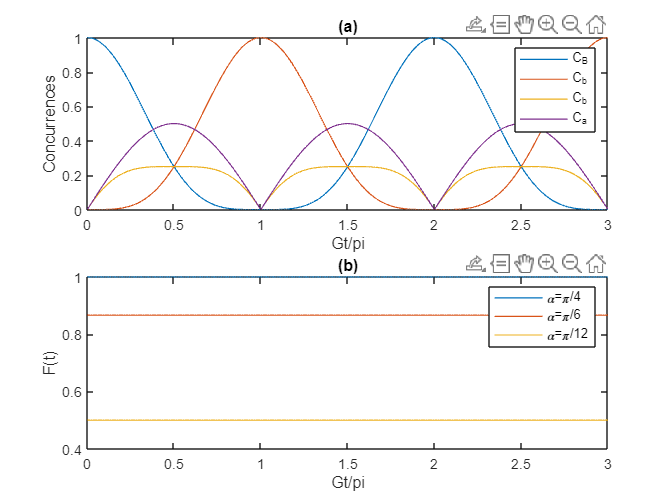


%---------------Everything at once for alpha=pi/4-------------
figure;
subplot(2,1,1)
plot(Gt/pi, Con_AB_1,LineWidth=0.75);
hold on;
plot(Gt/pi, Con_ab_1,LineWidth=0.75);
plot(Gt/pi, Con_Ab_1,LineWidth=0.75);
plot(Gt/pi, Con_Aa_1,LineWidth=0.75);
xlabel('Gt/pi');
ylabel('Concurrences');
legend('C_A_B','C_a_b','C_A_b','C_A_a');
title('(a)')

%---------------Entanglement Conservation-----------------------
Conservation1=Con_AB_1 + Con_ab_1 + 2*Con_Aa_1*abs(tan(alpha1)) - 2*Con_Ab_1;
Conservation2=Con_AB_2 + Con_ab_2 + 2*Con_Aa_2*abs(tan(alpha2)) - 2*Con_Ab_2;
Conservation3=Con_AB_3 + Con_ab_3 + 2*Con_Aa_3*abs(tan(alpha3)) - 2*Con_Ab_3;

subplot(2,1,2)
plot(Gt/pi, Conservation1,LineWidth=0.75);
hold on;
plot(Gt/pi, Conservation2,LineWidth=0.75);
plot(Gt/pi, Conservation3,LineWidth=0.75);
xlabel('Gt/pi');
ylabel('F(t)');
legend('\alpha=\pi/4','\alpha=\pi/6','\alpha=\pi/12');
title('(b)')

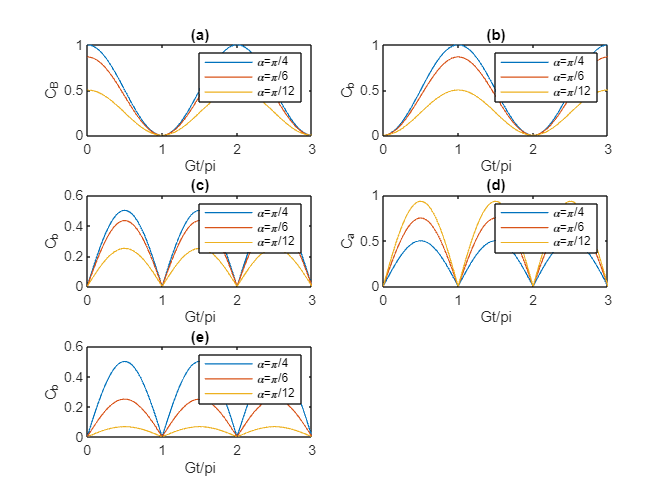


%For the PSI GROUP
Con2_AB_1=abs(sin(2*alpha1))*(cos(Gt/2)).^2;
Con2_AB_2=abs(sin(2*alpha2))*(cos(Gt/2)).^2;
Con2_AB_3=abs(sin(2*alpha3))*(cos(Gt/2)).^2;

Con2_ab_1=abs(sin(2*alpha1))*(sin(Gt/2)).^2;
Con2_ab_2=abs(sin(2*alpha2))*(sin(Gt/2)).^2;
Con2_ab_3=abs(sin(2*alpha3))*(sin(Gt/2)).^2;

Con2_Ab_1=1/2*abs(sin(2*alpha1))*abs(sin(Gt));
Con2_Ab_2=1/2*abs(sin(2*alpha2))*abs(sin(Gt));
Con2_Ab_3=1/2*abs(sin(2*alpha3))*abs(sin(Gt));

Con2_Aa_1=abs(sin(Gt))*(cos(alpha1))^2;
Con2_Aa_2=abs(sin(Gt))*(cos(alpha2))^2;
Con2_Aa_3=abs(sin(Gt))*(cos(alpha3))^2;

Con2_Bb_1=abs(sin(Gt))*(sin(alpha1))^2;
Con2_Bb_2=abs(sin(Gt))*(sin(alpha2))^2;
Con2_Bb_3=abs(sin(Gt))*(sin(alpha3))^2;

figure;
subplot(3,2,1)
plot(Gt/pi, Con2_AB_1,LineWidth=0.75);
hold on;
plot(Gt/pi, Con2_AB_2,LineWidth=0.75);
plot(Gt/pi, Con2_AB_3,LineWidth=0.75);
xlabel('Gt/pi');
ylabel('C_A_B');
legend('\alpha=\pi/4','\alpha=\pi/6','\alpha=\pi/12');
title("(a)")

subplot(3,2,2)
plot(Gt/pi, Con2_ab_1,LineWidth=0.75);
hold on;
plot(Gt/pi, Con2_ab_2,LineWidth=0.75);
plot(Gt/pi, Con2_ab_3,LineWidth=0.75);
xlabel('Gt/pi');
ylabel('C_a_b');
legend('\alpha=\pi/4','\alpha=\pi/6','\alpha=\pi/12');
title("(b)")

subplot(3,2,3)
plot(Gt/pi, Con2_Ab_1,LineWidth=0.75);
hold on;
plot(Gt/pi, Con2_Ab_2,LineWidth=0.75);
plot(Gt/pi, Con2_Ab_3,LineWidth=0.75);
xlabel('Gt/pi');
ylabel('C_A_b');
legend('\alpha=\pi/4','\alpha=\pi/6','\alpha=\pi/12');
title("(c)")

subplot(3,2,4)
plot(Gt/pi, Con2_Aa_1,LineWidth=0.75);
hold on;
plot(Gt/pi, Con2_Aa_2,LineWidth=0.75);
plot(Gt/pi, Con2_Aa_3,LineWidth=0.75);
xlabel('Gt/pi');
ylabel('C_A_a');
legend('\alpha=\pi/4','\alpha=\pi/6','\alpha=\pi/12');
title("(d)")

subplot(3,2,5)
plot(Gt/pi, Con2_Bb_1,LineWidth=0.75);
hold on;
plot(Gt/pi, Con2_Bb_2,LineWidth=0.75);
plot(Gt/pi, Con2_Bb_3,LineWidth=0.75);
xlabel('Gt/pi');
ylabel('C_B_b');
legend('\alpha=\pi/4','\alpha=\pi/6','\alpha=\pi/12');
title("(e)")

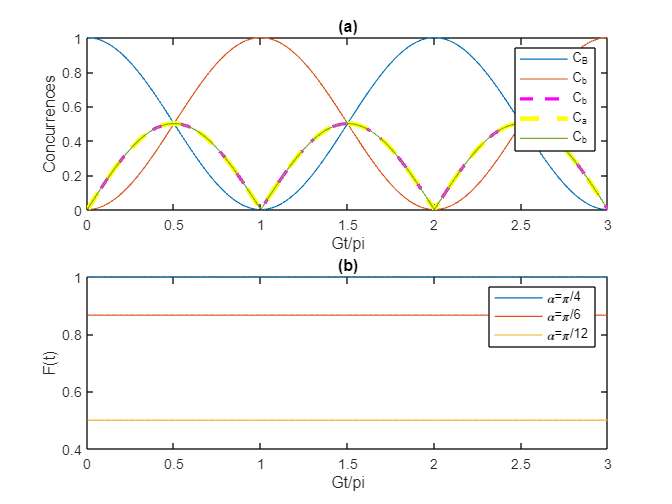


%All figures at once for PSI
figure;
subplot(2,1,1)
plot(Gt/pi, Con2_AB_1,LineWidth=0.75);
hold on;
plot(Gt/pi, Con2_ab_1,LineWidth=0.75);
plot(Gt/pi, Con2_Ab_1,LineWidth=2,Color="m",LineStyle="--");
plot(Gt/pi, Con2_Aa_1,"--y",LineWidth=3);
plot(Gt/pi, Con2_Bb_1,LineWidth=0.75);
xlabel('Gt/pi');
ylabel('Concurrences');
legend('C_A_B','C_a_b','C_A_b','C_A_a','C_B_b');
title('(a)')

%Entanglement conservation for the PSI
Conservation1_2=Con2_AB_1 +Con2_ab_1+ sin(alpha1)^2*Con2_Aa_1 -cos(alpha1).^2*Con2_Bb_1;
Conservation2_2=Con2_AB_2 +Con2_ab_2+ sin(alpha2)^2*Con2_Aa_2 -cos(alpha2).^2*Con2_Bb_2;
Conservation3_2=Con2_AB_3 +Con2_ab_3+ sin(alpha3)^2*Con2_Aa_3 -cos(alpha3).^2*Con2_Bb_3;

subplot(2,1,2)
plot(Gt/pi, Conservation1_2,LineWidth=0.75);
hold on;
plot(Gt/pi, Conservation2_2,LineWidth=0.75);
plot(Gt/pi, Conservation3_2,LineWidth=0.75);
xlabel('Gt/pi');
ylabel('F(t)');
legend('\alpha=\pi/4','\alpha=\pi/6','\alpha=\pi/12');
title('(b)')